addpath(genpath('../AMP'))
addpath('../algorithm')
%addpath('../outdated')

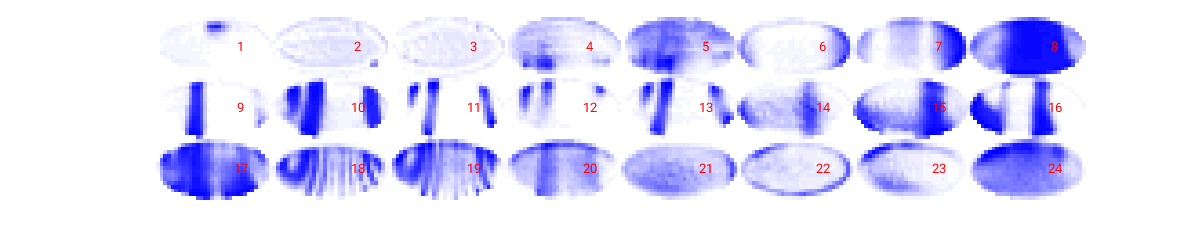

%show some images
load ../data32by16.mat
width = 32;
height = 16;
nrow = 3;
ncol = 8;
colorScale = '';
imageBatchDisplaySaveMemory(X,width,height,nrow,ncol,colorScale,0.5,template)


%addpath(genpath('../spams-matlab'))
optIn.tryBigampEM = 1;
optIn.tryKsvd = 1;
optIn.tryErspud = 1;

optIn.trySpams = 1;
optIn.tryBCD = 1;
%Specify maximum allowed trials
optIn.maxTrials = 1;
%Problem dimensions
optIn.M = 5; %size of signal
optIn.N = optIn.M; %size of dictionary
optIn.pos = 0;% set coef to be positive
optIn.L = ceil(20*optIn.N*log(optIn.N)); %From Spielman et al.

%SNR
optIn.SNR = 40;

%Specify coding mode (0 for OMP, 1 for TST)
%The specified function is used to compute a coding error for the
%resulting dictionary for each algorithm. TST may be significantly
%slower.
optIn.useTST = 0;

%Precondition option (enable to use a preconditioner for EM-BiG-AMP)
optIn.precondition = 0;


%Add paths
setup_DL

%% Problem Setup
load ../data32by16.mat
data = X;
param.K         = 21;         % dictionary size
param.iter      = 3000;       % number of iterations
param.mode      = 2;          % 1 if basis pursuit; 2 if lasso
param.lambda    = 1e-1;       % tolerance
param.numThreads = 1;
[true_dict, true_coef] = nmf(data, param);

num param iterD: 1
Online Dictionary Learning with no parameter 
Positivity constraints on D activated
Positivity constraints on alpha activated
mode Alpha 2
Cleaning activated 
batch size: 512
L: 21
lambda: 0
mode: 2
*****Online Dictionary Learning*****
Iteration: 0
Iteration: 1
Iteration: 2
Iteration: 3
Iteration: 4
Iteration: 5
Iteration: 6
Iteration: 7
Iteration: 8
Iteration: 9
Iteration: 10
Iteration: 11
Iteration: 12
Iteration: 13
Iteration: 14
Iteration: 15
Iteration: 16
Iteration: 17
Iteration: 18
Iteration: 19
Iteration: 20
Iteration: 21
Iteration: 22
Iteration: 23
Iteration: 24
Iteration: 25
Iteration: 26
Iteration: 27
Iteration: 28
Iteration: 29
Iteration: 30
Iteration: 31
Iteration: 32
Iteration: 33
Iteration: 34
Iteration: 35
Iteration: 36
Iteration: 37
Iteration: 38
Iteration: 39
Iteration: 40
Iteration: 41
Iteration: 42
Iteration: 43
Iteration: 44
Iteration: 45
Iteration: 46
Iteration: 47
Iteration: 48
Iteration: 49
Iteration: 50
Iteration: 51
Iteration: 52
Iteration: 53

Time elapsed : 45.7635


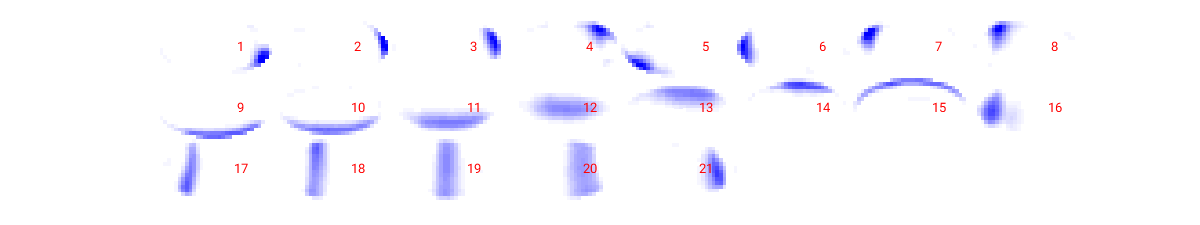

width = 32;
height = 16;
nrow = 3;
ncol = 8;
colorScale = '';
index = [3, 17, 6, 14, 19, 20, 11, 4,...
    2, 18, 7, 16, 5, 8, 9,...
    15, 10, 1, 12, 21, 13];
imageBatchDisplaySaveMemory(true_dict(:,index),width,height,nrow,ncol,colorScale,0.5,template)

[V, U] = pca(data, 'centered', false);
V = V';
transform = U(:,1:21);
newdata = V(1:21,:);

useTST = 0;

%Precondition
precondition = 0;

%Max trials
maxTrials = 5;

%Define problem dimensions
M = 21;
L = size(newdata,2);
N = 21;
K = 10;

%Set options
opt = BiGAMPOpt; %initialize the options object
opt.nit = 500; %limit iterations

%Set sizes
problem = BiGAMPProblem();
problem.M = M;
problem.N = N;
problem.L = L;


%% Build the dictionary
A = normalize_columns(true_dict);

%Dictionary error function
dictionary_error_function =...
    @(q) 20*log10(norm(A -...
    transform * q * find_permutation(A,transform * q),'fro')/norm(A,'fro'));



%% Compute coefficient vectors

%Compute true vectors with exactly K non-zeroes in each
X = true_coef;

%% Form the output channel

%Compute noise free output
Z = transform\A*X;

%Define the error function
error_function = @(qval) 20*log10(norm(qval - Z,'fro') / norm(Z,'fro'));
opt.error_function = error_function;

%Noisy output channel
Y = newdata;

%Coding error
coding_error_function = @(q) 20*log10(coding_error(Y,q,K,useTST));


%Initialize results as empty
results = [];


%Silence
opt.verbose = false;

%Coding
bestError = inf;
bestSparsity = inf;

%Compute preconditioner
if precondition
    Q = chol(inv(Y*Y'));
else
    Q = 1;
end

%Define the error function
QZ = Q*newdata; %Using (possibly) noisy data for error function
error_function2 = @(qval) 20*log10(norm(qval - QZ,'fro') / norm(QZ,'fro'));
opt.error_function = error_function2;

tstart = tic;
for trial = 1:maxTrials
    
    %Run EM-BiGAMP
    [estFinTemp,~,~,estHistEMtemp] = ...
        EMBiGAMP_DL(Q*newdata,problem,opt);
    
    %Correct the dictionary
    estFinTemp.Ahat = Q \ estFinTemp.Ahat;
    
    %Reset error function
    opt.error_function = error_function;
    
    %If the sparisty is better and the error is very small or better
    if bestError > dictionary_error_function(estFinTemp.Ahat)
        
        %Update
        bestSparsity = sum(sum(estHistEMtemp.p1));
        bestError = estHistEMtemp.errZ(end);
        AhatOptEM = estFinTemp.Ahat;
        estHistEM = estHistEMtemp;
        p1EM = estHistEMtemp.p1;
        
        %Notify user
        disp(['Accepting new result. Error: ' num2str(bestError)...
            '  Average sparsity: ' num2str(bestSparsity/L)...
            '  Max Sparsity: ' num2str(max(sum(p1EM)))])
    end
    %keyboard
end

Accepting new result. Error: -42.2692  Average sparsity: 13.9966  Max Sparsity: 19.8669


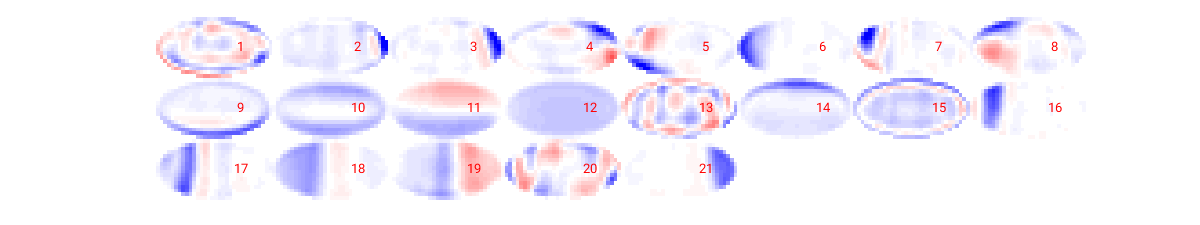

tEMGAMP = toc(tstart);

%Save results
loc = length(results) + 1;
results{loc}.name = 'EM-BiG-AMP'; %#ok<*AGROW>
results{loc}.err = estHistEM.errZ(end);
results{loc}.time = tEMGAMP;
results{loc}.errHist = estHistEM.errZ;
results{loc}.timeHist = estHistEM.timing;
results{loc}.dict = AhatOptEM;
results{loc}.dictError = dictionary_error_function(results{loc}.dict);
results{loc}.codingError =...
    coding_error_function(results{loc}.dict);
imageBatchDisplaySaveMemory(transform * results{loc}.dict * find_permutation(A(:,index), transform * results{loc}.dict),...
    width,height,nrow,ncol,colorScale,0.5,template)

%Build params
spams_param = [];
spams_param.K = N;
spams_param.mode = 2;
spams_param.lambda = 1/sqrt(N);
spams_param.iter = 1000;
spams_param.verbose = 0;
spams_param.numThreads = 1;


%Trials
bestSPAMSerror = inf;

tstart = tic;
for trial = 1:maxTrials
    
    %Do it
    A_spamsTemp = mexTrainDL(data(:,randperm(size(data,2))),spams_param);
    
    
    SPAMSerrorTemp = dictionary_error_function(transform\A_spamsTemp);
    
    %Update the estimate if this result was superior
    if SPAMSerrorTemp < bestSPAMSerror
        SPAMSerror = SPAMSerrorTemp;
        bestSPAMSerror = SPAMSerror;
        A_spams = A_spamsTemp;
        disp(['Updating Solution. Error was: '...
            num2str(SPAMSerror) ' dB'])
    end
    
end

Updating Solution. Error was: -5.116 dB


Updating Solution. Error was: -5.8697 dB


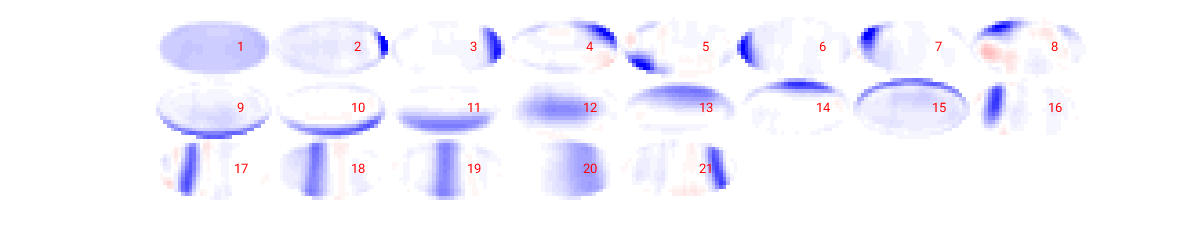

tspams = toc(tstart);


%Save results
loc = length(results) + 1;
results{loc}.name = 'SPAMS'; %#ok<*AGROW>
results{loc}.err = dictionary_error_function(transform\A_spams);
results{loc}.time = tspams;
results{loc}.errHist = results{loc}.err;
results{loc}.timeHist = zeros(size(results{loc}.errHist));
results{loc}.dict = A_spams;
results{loc}.dictError = dictionary_error_function(transform\results{loc}.dict);
results{loc}.codingError =...
    coding_error_function(transform\results{loc}.dict);
imageBatchDisplaySaveMemory(results{loc}.dict * find_permutation(A(:,index), results{loc}.dict),...
    width,height,nrow,ncol,colorScale,0.5,template)

%Build params
bcd_option = [];
bcd_option.MAXITER = 100;
bcd_option.thres1 = 1e-3;
bcd_options.thres2 = 1;
bcd_option.verbose = 0;
%bcd_option.dict = normalize_columns(transform\A_spams);
bcd_ratio = 1;

%Trials
bestBCDerror = inf;

tstart = tic;
for trial = 1:maxTrials
    
    %Do it
    A_bcdTemp = DL_BCD(Y(:,randsample(L, ceil(L*bcd_ratio))),bcd_option);
    
    
    BCDerrorTemp = dictionary_error_function(A_bcdTemp);
    
    %Update the estimate if this result was superior
    if BCDerrorTemp < bestBCDerror
        BCDerror = BCDerrorTemp;
        bestBCDerror = BCDerror;
        A_bcd = A_bcdTemp;
        disp(['Updating Solution. Error was: '...
            num2str(BCDerror) ' dB'])
    end
    
end

Updating Solution. Error was: -2.3089 dB


Updating Solution. Error was: -2.6308 dB


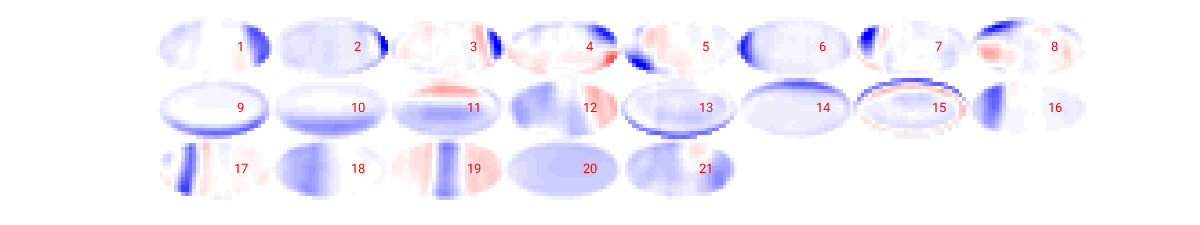

tbcd = toc(tstart);


%Save results
loc = length(results) + 1;
results{loc}.name = 'BCD'; %#ok<*AGROW>
results{loc}.err = dictionary_error_function(A_bcd);
results{loc}.time = tbcd;
results{loc}.errHist = results{loc}.err;
results{loc}.timeHist = zeros(size(results{loc}.errHist));
results{loc}.dict = A_bcd;
results{loc}.dictError = dictionary_error_function(results{loc}.dict);
results{loc}.penalty = 1;
results{loc}.codingError =...
    coding_error_function(results{loc}.dict);
imageBatchDisplaySaveMemory(transform * results{loc}.dict * find_permutation(A(:,index), transform * results{loc}.dict),...
    width,height,nrow,ncol,colorScale,0.5,template)

%Build params
ksvd_params = [];
ksvd_params.data = Y;
ksvd_params.Tdata = K;
ksvd_params.dictsize = N;
ksvd_params.iternum = 100;
ksvd_params.exacty = 1;

%Trials
bestKSVDerror = inf;
tstart = tic;
for trial = 1:maxTrials
    
    %Do it
    
    [A_ksvdtemp,~,err_ksvdtemp] = ksvd(ksvd_params);
    
    
    %Fix error
    err_ksvdtemp = err_ksvdtemp.^2 * numel(Y);
    
    %Update the estimate if this result was superior
    if dictionary_error_function(A_ksvdtemp) < bestKSVDerror
        bestKSVDerror = err_ksvdtemp(end);
        err_ksvd = err_ksvdtemp;
        A_ksvd = A_ksvdtemp;
        disp(['Updating Solution. Error was: '...
            num2str(10*log10(err_ksvd(end)/norm(Z,'fro')^2))])
    end
    
end

Updating Solution. Error was: -11.943


Updating Solution. Error was: -11.8508


Updating Solution. Error was: -11.6025


Updating Solution. Error was: -11.3765


Updating Solution. Error was: -11.8506


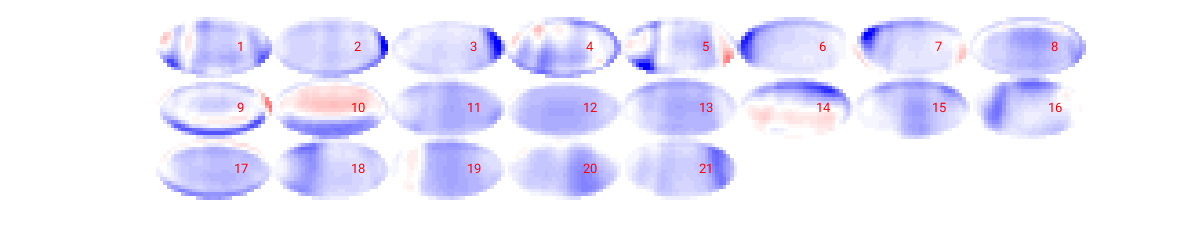

tksvd = toc(tstart);

%Save results
loc = length(results) + 1;
results{loc}.name = 'K-SVD'; %#ok<*AGROW>
results{loc}.err = 10*log10(err_ksvd(end)/norm(Z,'fro')^2);
results{loc}.time = tksvd;
results{loc}.errHist = 10*log10(err_ksvd/norm(Z,'fro')^2);
results{loc}.timeHist = zeros(size(err_ksvd));
results{loc}.dict = A_ksvd;
results{loc}.dictError = dictionary_error_function(results{loc}.dict);
results{loc}.codingError =...
    coding_error_function(results{loc}.dict);
imageBatchDisplaySaveMemory(transform * results{loc}.dict * find_permutation(A(:,index), transform*results{loc}.dict),...
    width,height,nrow,ncol,colorScale,0.5,template)

%----------------BiG-EM-AMP------------------
%
%Silence
opt.verbose = false;

%Coding
bestError = inf;
bestSparsity = inf;

%Compute preconditioner
if precondition
    Q = chol(inv(Y*Y'));
else
    Q = 1;
end

%Define the error function
QZ = Q*Z; %Using (possibly) noisy data for error function
error_function2 = @(qval) 20*log10(norm(qval - QZ,'fro') / norm(QZ,'fro'));
opt.error_function = error_function2;

tstart = tic;
for trial = 1:maxTrials
    
    %Run EM-BiGAMP
    [estFinTemp,~,~,estHistEMtemp] = ...
        EMBiGAMP_DL(Q*Z,problem,opt);
    
    %Correct the dictionary
    estFinTemp.Ahat = Q \ estFinTemp.Ahat;
    
    %Reset error function
    opt.error_function = error_function;
    
    %If the sparisty is better and the error is very small or better
    if bestError > dictionary_error_function(estFinTemp.Ahat)
        
        %Update
        bestSparsity = sum(sum(estHistEMtemp.p1));
        bestError = estHistEMtemp.errZ(end);
        AhatOptEM = estFinTemp.Ahat;
        estHistEM = estHistEMtemp;
        p1EM = estHistEMtemp.p1;
        
        %Notify user
        disp(['Accepting new result. Error: ' num2str(bestError)...
            '  Average sparsity: ' num2str(bestSparsity/L)...
            '  Max Sparsity: ' num2str(max(sum(p1EM)))])
    end
    %keyboard
end

Accepting new result. Error: -19.7947  Average sparsity: 8.7536  Max Sparsity: 16.4381


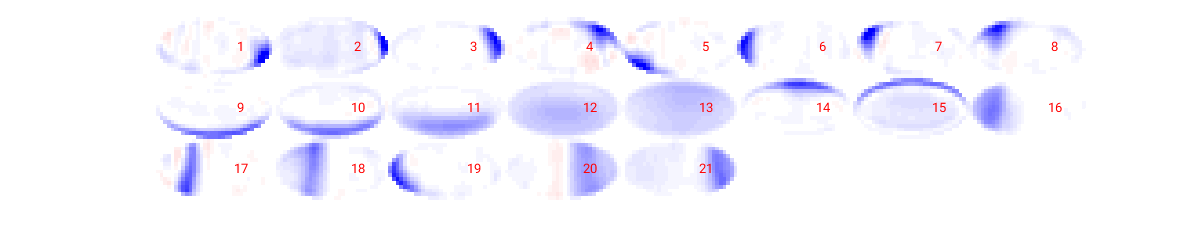

tEMGAMP = toc(tstart);

%Save results
loc = length(results) + 1;
results{loc}.name = 'EM-BiG-AMP'; %#ok<*AGROW>
results{loc}.err = estHistEM.errZ(end);
results{loc}.time = tEMGAMP;
results{loc}.errHist = estHistEM.errZ;
results{loc}.timeHist = estHistEM.timing;
results{loc}.dict = AhatOptEM;
results{loc}.dictError = dictionary_error_function(results{loc}.dict);
results{loc}.codingError =...
    coding_error_function(results{loc}.dict);
imageBatchDisplaySaveMemory(transform * results{loc}.dict * find_permutation(A(:,index), transform * results{loc}.dict),...
    width,height,nrow,ncol,colorScale,0.5,template)

%Build params
bcd_option = [];
bcd_option.MAXITER = 100;
bcd_option.thres1 = 1e-3;
bcd_options.thres2 = 1000;
bcd_option.verbose = 0;
%bcd_option.dict = normalize_columns(transform\A_spams);
bcd_ratio = 1;

%Trials
bestBCDerror = inf;

tstart = tic;
for trial = 1:1
    
    %Do it
    A_bcdTemp = DL_BCD(Z(:,randsample(L, ceil(L*bcd_ratio))),bcd_option);
    
    
    BCDerrorTemp = dictionary_error_function(A_bcdTemp);
    
    %Update the estimate if this result was superior
    if BCDerrorTemp < bestBCDerror
        BCDerror = BCDerrorTemp;
        bestBCDerror = BCDerror;
        A_bcd = A_bcdTemp;
        disp(['Updating Solution. Error was: '...
            num2str(BCDerror) ' dB'])
    end
end

Undefined function or variable 'Z'.

tbcd = toc(tstart);


%Save results
loc = length(results) + 1;
results{loc}.name = 'BCD'; %#ok<*AGROW>
results{loc}.err = dictionary_error_function(A_bcd);
results{loc}.time = tbcd;
results{loc}.errHist = results{loc}.err;
results{loc}.timeHist = zeros(size(results{loc}.errHist));
results{loc}.dict = A_bcd;
results{loc}.dictError = dictionary_error_function(results{loc}.dict);
results{loc}.penalty = 1;
results{loc}.codingError =...
    coding_error_function(results{loc}.dict);
imageBatchDisplaySaveMemory(transform * results{loc}.dict * find_permutation(A(:,index), transform * results{loc}.dict),...
    width,height,nrow,ncol,colorScale,0.5,template)

% Er-Spud
%[Aerspud,Xerspud] = ER_SpUD_SC(Y);
tic;
[Aerspud,Xerspud]=dl_spud(Y);   %#ok<NASGU>

1 row(s) of X recovered, nonzero # in the new row:1635
2 row(s) of X recovered, nonzero # in the new row:1634
3 row(s) of X recovered, nonzero # in the new row:1635
4 row(s) of X recovered, nonzero # in the new row:1633
5 row(s) of X recovered, nonzero # in the new row:1634
6 row(s) of X recovered, nonzero # in the new row:1635
7 row(s) of X recovered, nonzero # in the new row:1635
8 row(s) of X recovered, nonzero # in the new row:1635
9 row(s) of X recovered, nonzero # in the new row:1635
10 row(s) of X recovered, nonzero # in the new row:1634
11 row(s) of X recovered, nonzero # in the new row:1634
12 row(s) of X recovered, nonzero # in the new row:1635
13 row(s) of X recovered, nonzero # in the new row:1635
14 row(s) of X recovered, nonzero # in the new row:1635
15 row(s) of X recovered, nonzero # in the new row:1635
16 row(s) of X recovered, nonzero # in the new row:1635
17 row(s) of X recovered, nonzero # in the new row:1635
18 row(s) of X recovered, nonzero # in the new row:1636
1

tErspud = toc;

Error using toc
You must call TIC without an output argument before calling TOC without an input argument.


%Save results
loc = length(results) + 1;
results{loc}.name = 'ER-SpUD (proj)'; %#ok<*AGROW>
results{loc}.err = dictionary_error_function(Aerspud);
results{loc}.time = tErspud;
results{loc}.errHist = results{loc}.err;
results{loc}.timeHist = zeros(size(results{loc}.errHist));
results{loc}.dict = Aerspud;
results{loc}.dictError = dictionary_error_function(results{loc}.dict);
results{loc}.codingError =...
    coding_error_function(results{loc}.dict);

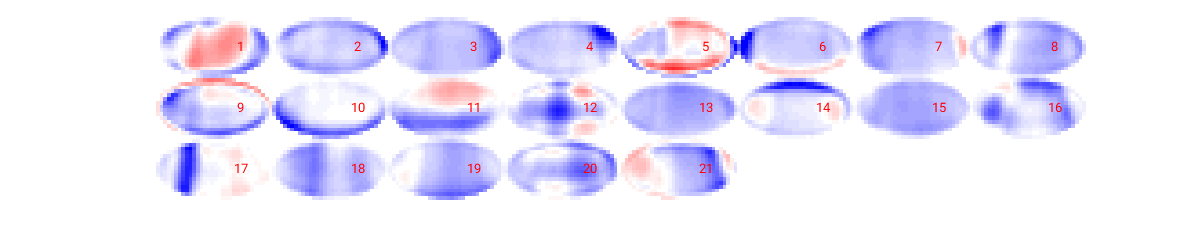


imageBatchDisplaySaveMemory(transform * results{loc}.dict * find_permutation(A(:,index), transform * results{loc}.dict),...
    width,height,nrow,ncol,colorScale,0.5,template)